# 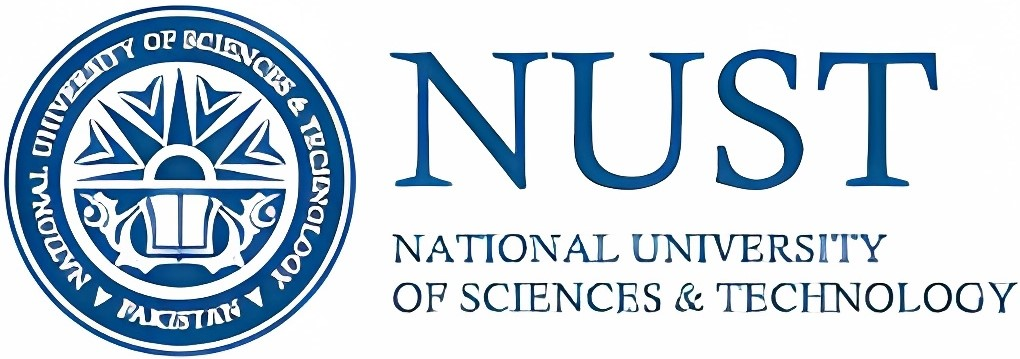

# **EE330 – Assignment 2**

**Group Members**

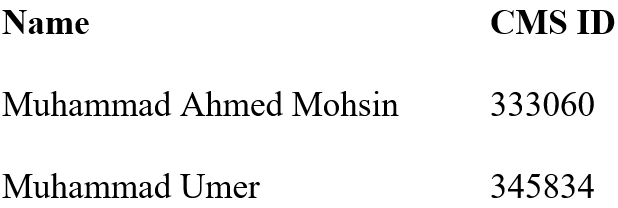

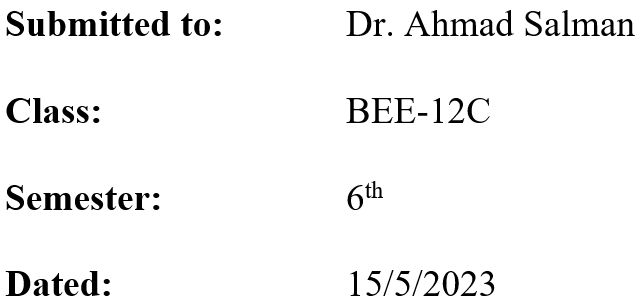

## Introduction

Filter designing is an essential aspect of signal processing, which involves the selection of a suitable filter to process a signal. In signal processing, filters are used to extract relevant information from a signal or to remove unwanted noise or interference. The process of designing a filter involves selecting the type of filter, choosing the filter parameters, and optimizing the filter design to meet the desired specifications. The purpose of this assignment is to explore and analyze the design strategies to obtain the desired response.

## Task 1

From your textbook (as uploaded to LMS already), see examples 7.5 and 7.6. Do these exercises on paper by hand, write down the characteristic equations of Chebyshev and Elliptic lowpass filters (from literature). Find the poles/zeros and/or coefficients of the designed discrete-time filters. Using coefficients, plot the magnitude response in both examples using MATLAB. The plot should be complete in title and x-axis and y-axis units.

### **Chebyshev Filter Design**

#### **Written Calculations**

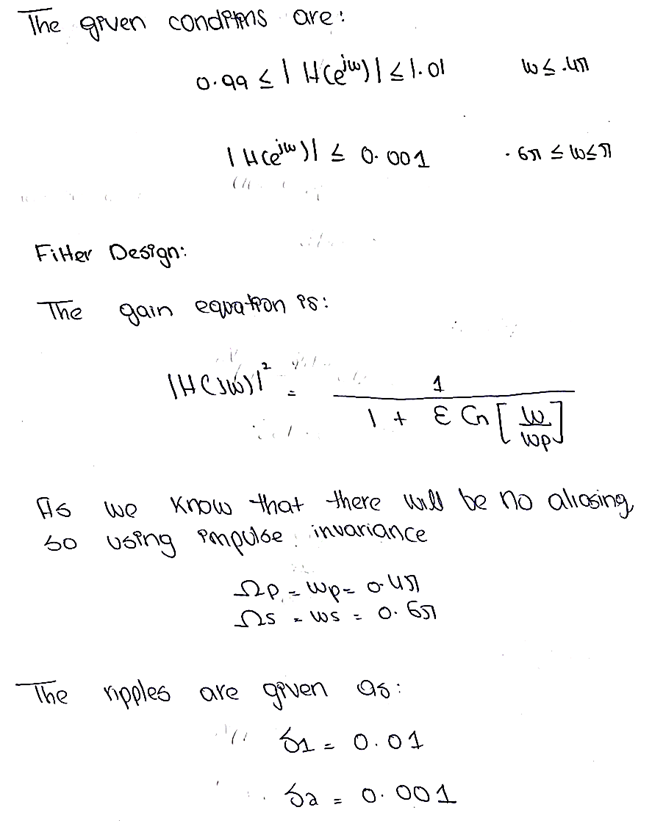

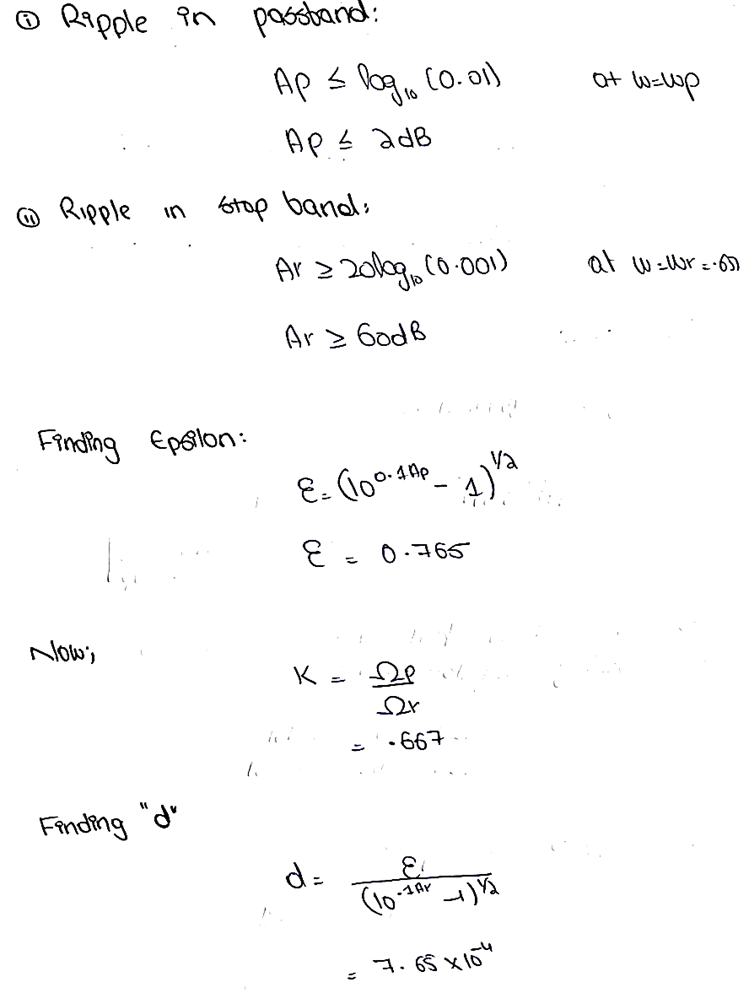

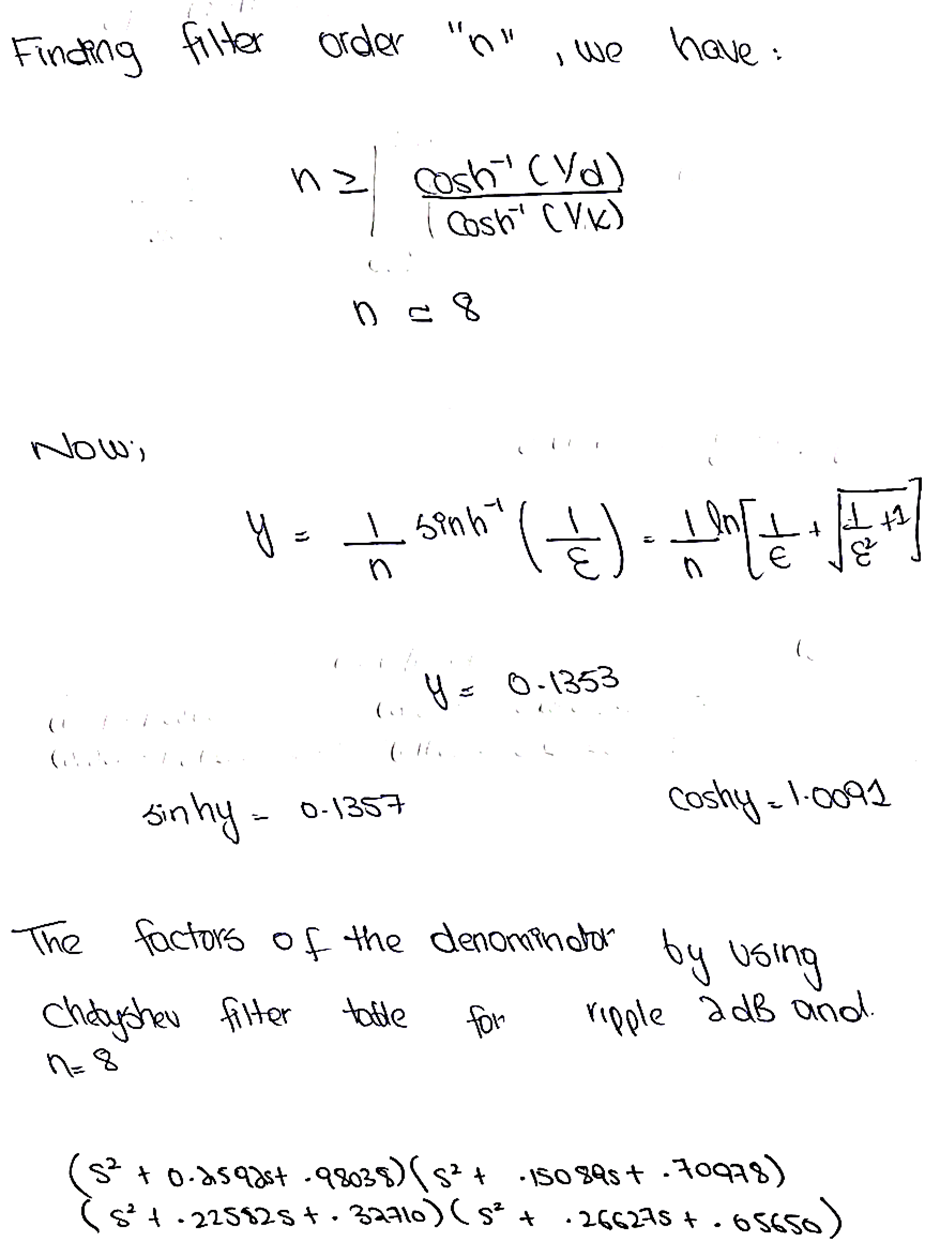

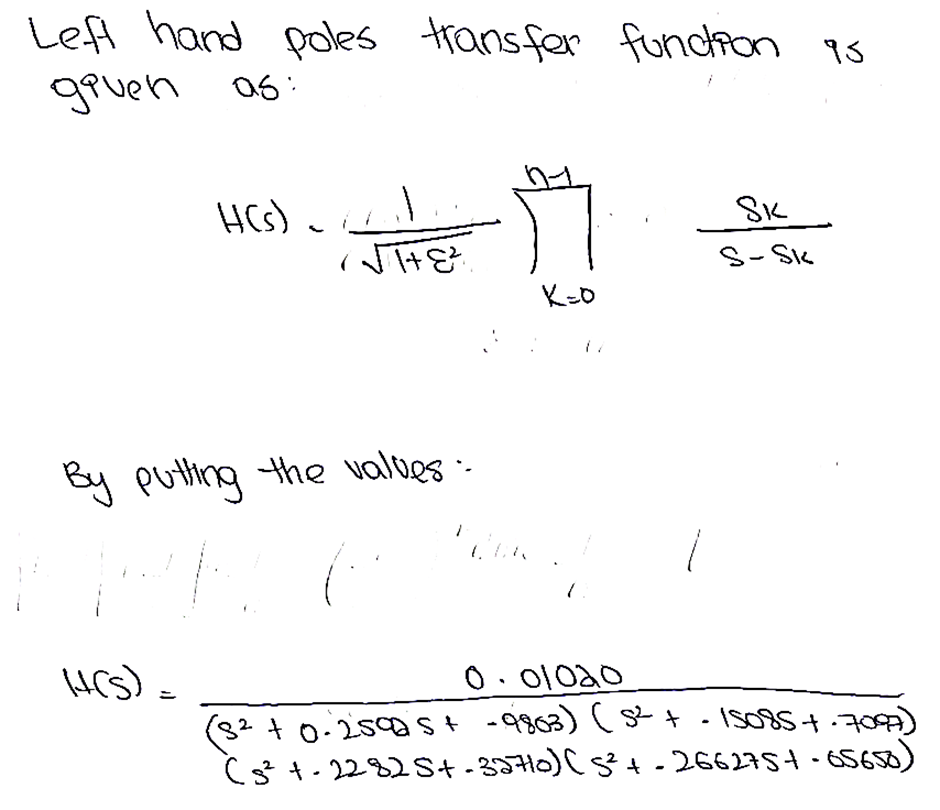

#### **MATLAB Code**

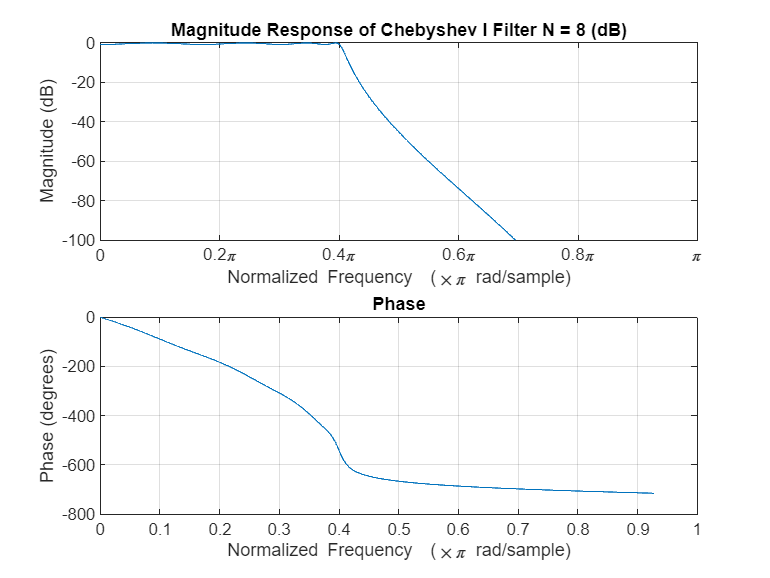

% The given Specifications are
w_p = 0.4 * pi;
w_s = 0.6 * pi;
ripple = 0.01;
Ap = -log10(0.01); % at w=wp (Ripple Magnitude)
Ar = -20 * log10(0.001); % At wr=0.6pi (Rejection magnitude)
epsilion = sqrt((10 ^ (0.1 * Ap) - 1));

% Finding ratio wp/wr;
k = w_p / w_s;

% Finding d
d = epsilion / sqrt((10 ^ (0.1 * Ar) - 1));
% Finding filter order
n = floor(acosh(1 / d) / acosh(1 / k));

% Calculating y
y = (1 / n) * (asinh(1 / epsilion));

% Plotting the filter by using the calculated values
[b, a] = cheby1(n, epsilion, (w_p / pi));
figure(1)
freqz(b, a, 1000);
axis([-inf inf -100 0])
xticks([0 0.2 0.4 0.6 0.8 0.999])
xticklabels({'0', '0.2\pi', '0.4\pi', '0.6\pi', '0.8\pi', '\pi'})
xlabel('Normalized Frequency  (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
title('Magnitude Response of Chebyshev I Filter N = 8 (dB)');

### **Elliptic Filter Design**

#### **Written Calculations**

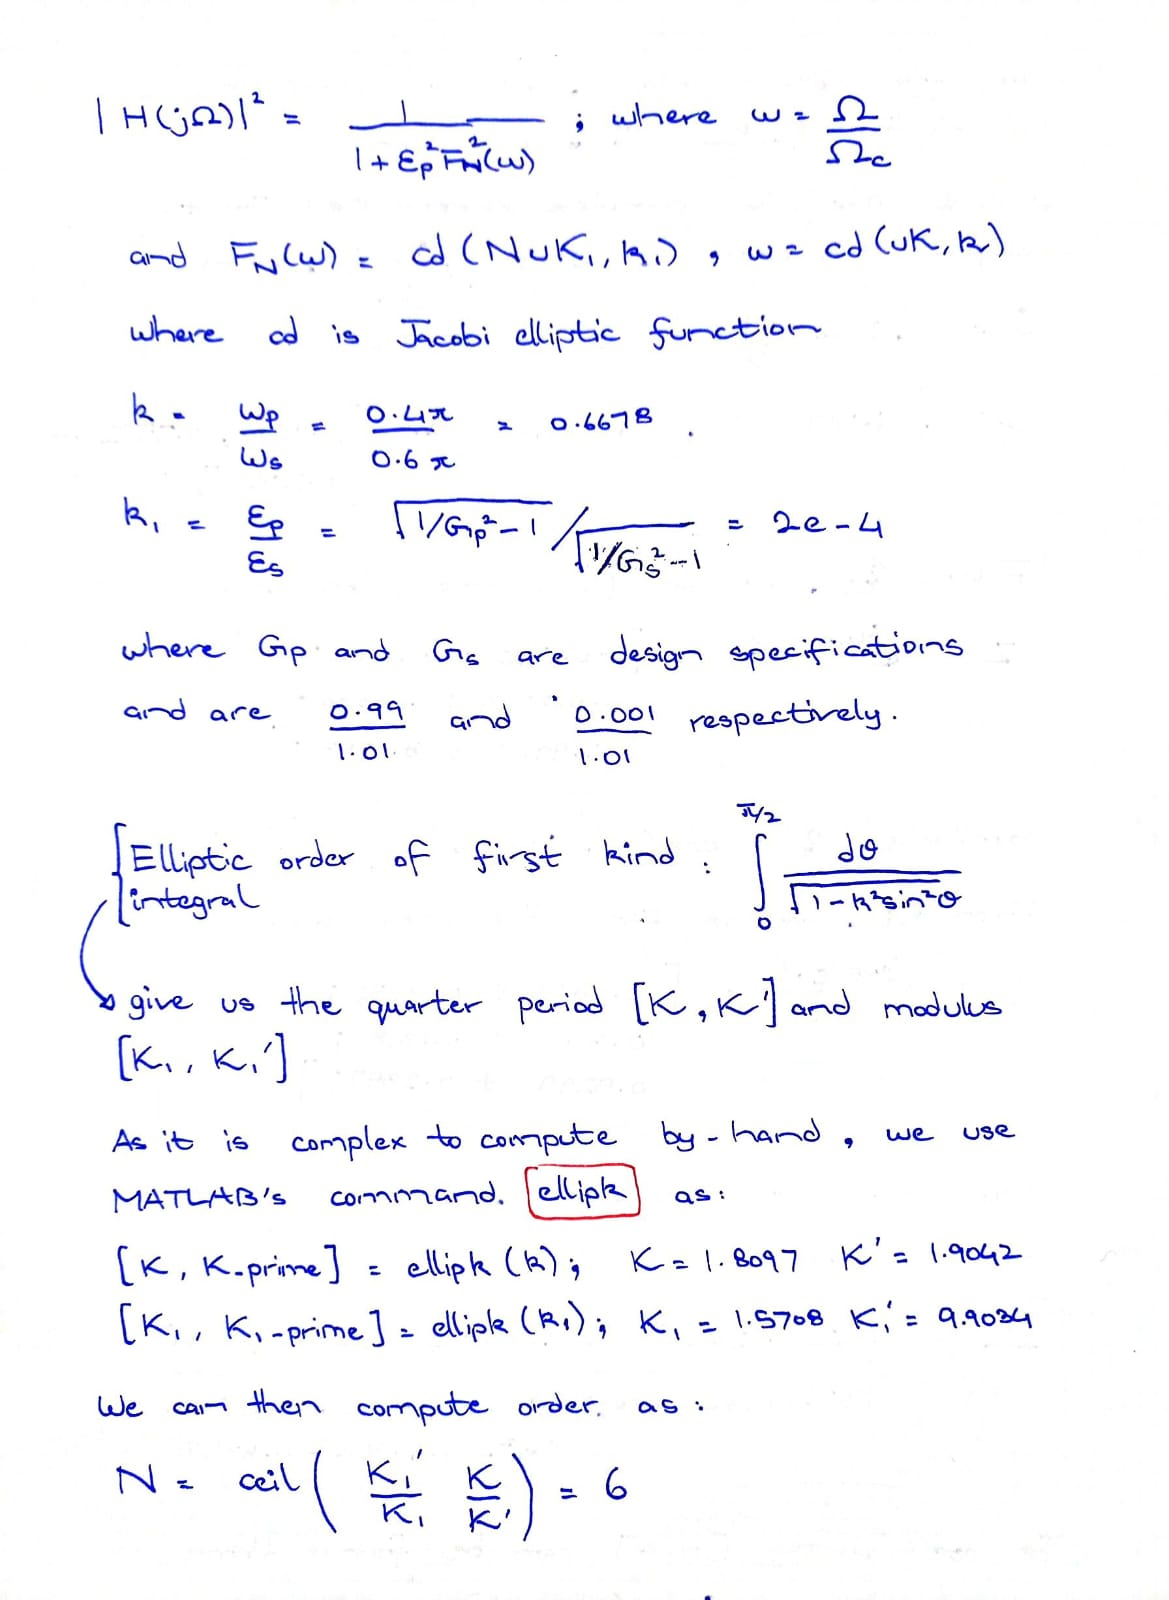

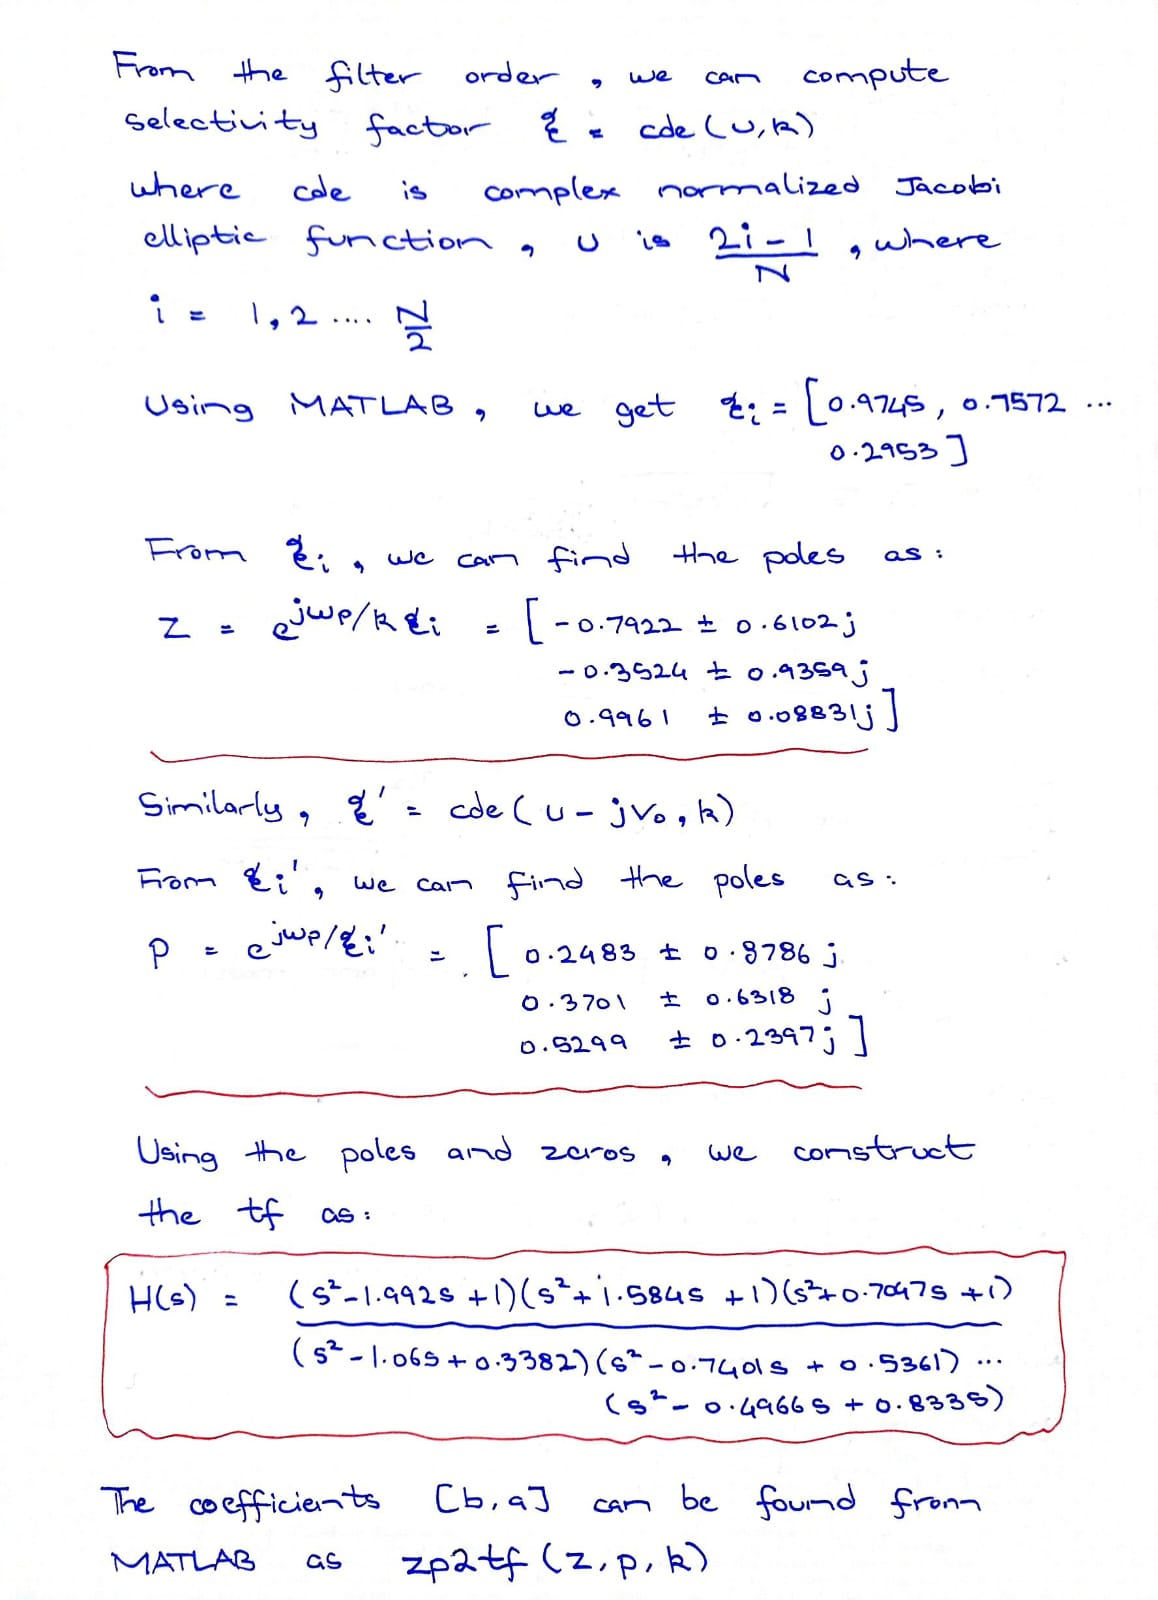

#### **MATLAB Code**

% The given specifications are
G_p = 0.99/1.01;
G_s = 0.001/1.01;
T = 1;
omega_p = 2 / T * tan(0.4 * pi / 2);
omega_s = 2 / T * tan(0.6 * pi / 2);
epsilon_p = sqrt(1 / G_p ^ 2 - 1);
epsilon_s = sqrt(1 / G_s ^ 2 - 1);

% calculate filter order
k = (omega_p * 1.6336/1.4531) / (omega_s * 1.9578/2.7528);
k1 = epsilon_p / epsilon_s;
[K, K_prime] = ellipk(k);
[K1, K1_prime] = ellipk(k1);

N = ceil((K1_prime / K1) / (K_prime / K));
k = ellipdeg(N, k1);

L = floor(N / 2);
r = mod(N, 2);
i = (1:L)';

% calculate poles and zeros
u = (2 * i - 1) / N;
zeta_i = cde(u, k);
z_a = (omega_p * 1.6336/1.4531) * 1i ./ (k * zeta_i);
v0 = -1i * asne(1i / epsilon_p, k1) / N;
p_a = (omega_p * 1.6336/1.4531) * 1i * cde(u - 1i * v0, k);
p_a0 = (omega_p * 1.6336/1.4531) * 1i * sne(1i * v0, k);
z = cplxpair([exp(z_a); conj(exp(z_a))]);
p = cplxpair([exp(p_a); conj(exp(p_a))]);

% calculate coefficients
b = [ones(L, 1), -2 * real(1 ./ z_a), abs(1 ./ z_a) .^ 2];
a = [ones(L, 1), -2 * real(1 ./ p_a), abs(1 ./ p_a) .^ 2];

% add extra pole/zero if N is odd
if r == 0
    b = [G_p, 0, 0; b];
    a = [1, 0, 0; a];
else
    b = [1, 0, 0; b];
    a = [1, -real(1 / p_a0), 0; a];
end

% frequency response
w = linspace(0, pi, 2048);
H = freq_resp(b, a, w);

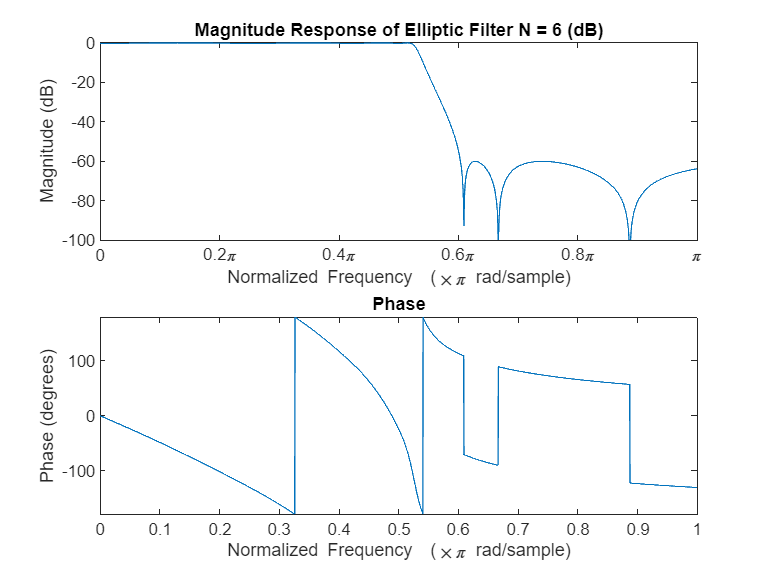

% magnitude response dB
figure(2)
subplot(211)
plot(w, 20 * log10(abs(H)));
axis([-inf inf -100 0])
xticks([0 (0.2 * pi) (0.4 * pi) (0.6 * pi) (0.8 * pi) pi])
xticklabels({'0', '0.2\pi', '0.4\pi', '0.6\pi', '0.8\pi', '\pi'})
xlabel('Normalized Frequency  (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
title('Magnitude Response of Elliptic Filter N = 6 (dB)');
subplot(212)
plot(w / pi, angle(H) * 180/pi);
axis([0 1 -inf inf])
xlabel('Normalized Frequency  (\times\pi rad/sample)');
ylabel('Phase (degrees)');
title('Phase');

## Task 2

In MATLAB, load a clean and noisy signal (uploaded to LMS), design a filter to suppress all frequencies except 1kHz and 1.5kHz. You are only allowed to use a 2nd order Butterworth bandpass filter and a 2nd order Butterworth band stop filter. Devise a scheme to achieve your target with a combination of these two filters. The sampling frequency of the signal is 6kHz.

- Plot clean and noisy signals as well as their frequency spectrums (recall labs). The x-axis and y-axis should be correctly labeled. The x-axis should be in Hz while y-axis should be spectral magnitude.

- Design and plot bandpass and band stop filters and plot their magnitude and phase responses. You can use MATLAB command “butter”. Apply the filters on the noisy signal and plot the output.

### Devised Approach

We remove noise from a given signal by first applying a bandstop filter to remove unwanted frequencies. A bandstop filter is a type of filter that allows frequencies within a certain range to pass through, while blocking frequencies outside of that range. In this case, we want to block the unwanted frequencies that are causing noise in the signal.

Once the bandstop filter has removed the unwanted frequencies, we then apply a bandpass filter to keep the desired frequencies. A bandpass filter is a type of filter that allows frequencies within a certain range to pass through, while blocking frequencies outside of that range. In this case, we want to allow the desired frequencies to pass through, while blocking any remaining noise.

### MATLAB Code

% Initializing
load('data.mat')
fs = 6e3; % sampling frequency
N = 2*fs; % number of samples
t = linspace(0, 1, 500);
df = fs / N;
index = -N / 2:(N / 2) - 1;
f = (df * index);
X = fftshift(fft(x, N)); % compute the DFT of x
Xn = fftshift(fft(xn, N)); % compute the DFT of xn

% plot the original signal (t and F)
figure(1)
subplot(211)

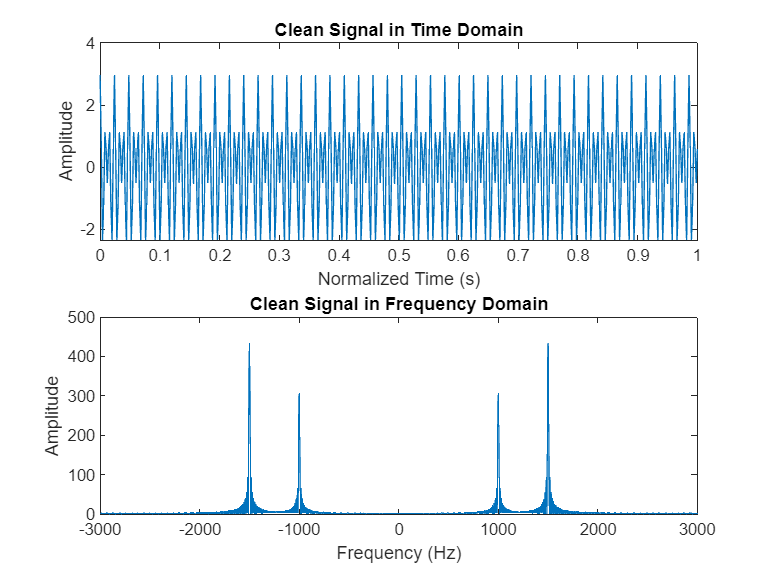

plot(t, x)
title('Clean Signal in Time Domain')
xlabel('Normalized Time (s)')
ylabel('Amplitude')
subplot(212)
plot(f, abs(X))
title('Clean Signal in Frequency Domain')
xlabel('Frequency (Hz)')
ylabel('Amplitude')

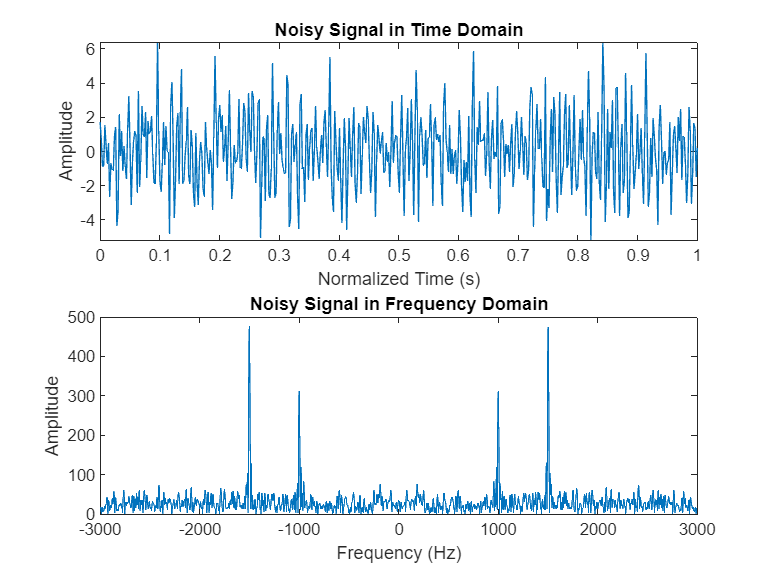

% plot the noisy signal (t and F)
figure(2)
subplot(211)
plot(t, xn)
title('Noisy Signal in Time Domain')
xlabel('Normalized Time (s)')
ylabel('Amplitude')
subplot(212)
plot(f, abs(Xn))
title('Noisy Signal in Frequency Domain')
xlabel('Frequency (Hz)')
ylabel('Amplitude')

f1 = 1e3;
f2 = 1.5e3;
[b_bs, a_bs] = butter(2, [f1 f2]/(fs/2), 'stop');
xn_bs = filter(b_bs, a_bs, xn);
Xn_bs = fftshift(fft(xn_bs, N)); % compute the DFT of xn

% Bandpass Filter
f1 = 1e3;
f2 = 1.5e3;
[b_bp, a_bp] = butter(2, [f1 f2]/(fs/2), 'bandpass');
xn_bp = filter(b_bp, a_bp, xn_bs);
Xn_bp = fftshift(fft(xn_bp, N)); % compute the DFT of xn

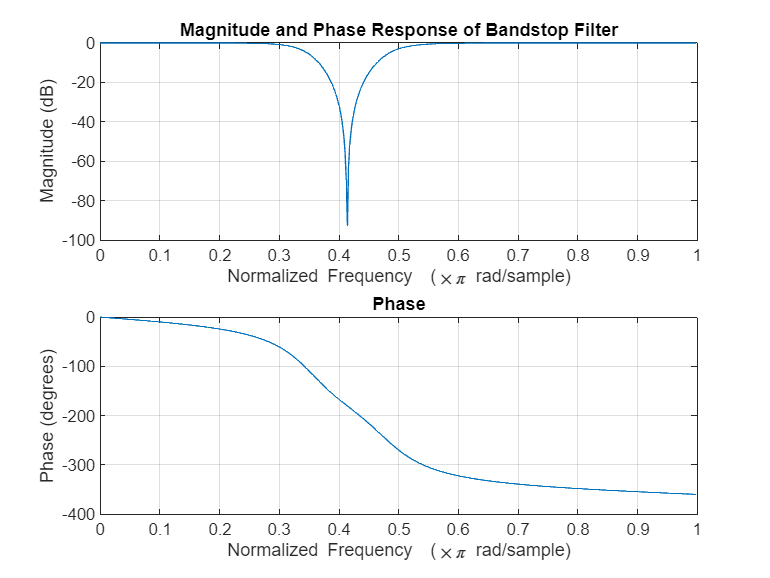

% Magnitude and phase response plots
figure(3)
freqz(b_bs, a_bs)
title('Magnitude and Phase Response of Bandstop Filter')

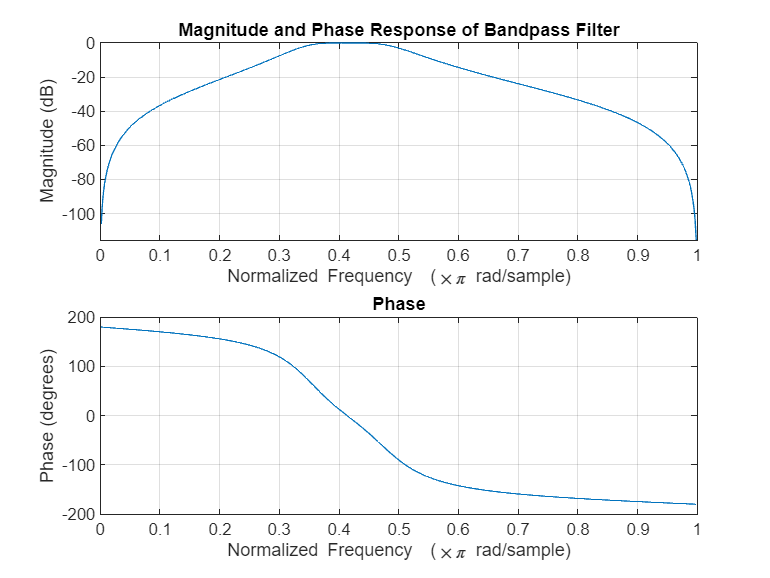

figure(4)
freqz(b_bp, a_bp)
title('Magnitude and Phase Response of Bandpass Filter')

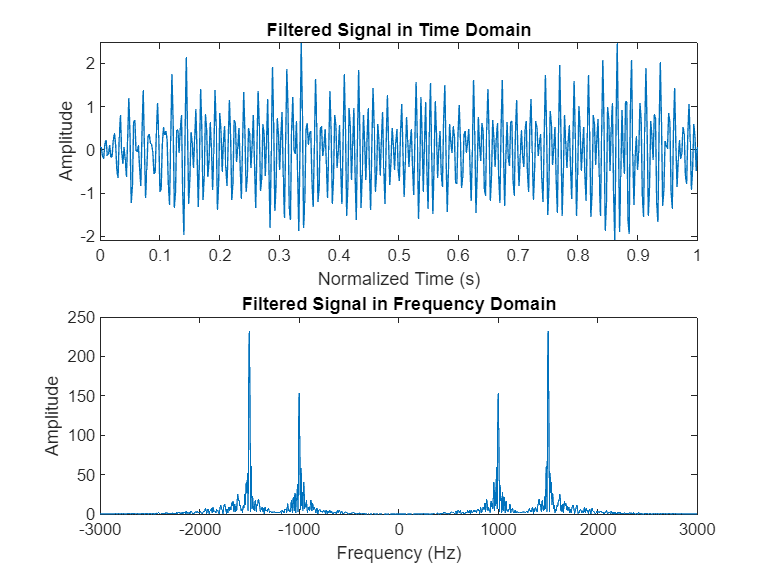

% Plotting the filtered output
figure(5)
subplot(211)
plot(t, xn_bp)
title('Filtered Signal in Time Domain')
xlabel('Normalized Time (s)')
ylabel('Amplitude')
subplot(212)
plot(f, abs(Xn_bp))
title('Filtered Signal in Frequency Domain')
xlabel('Frequency (Hz)')
ylabel('Amplitude')

## Conclusion

In conclusion, filter designing is an essential aspect of signal processing. There are many different types of filters available, each with its own advantages and disadvantages. The type of filter that is best suited for a particular application will depend on the specific requirements of that application. In this assignment, we explored two different methods for designing filters: Elliptic and Chebyshev. We also explored a strategy for designing a band stop filter followed by a bandpass filter. This strategy can be used to achieve a very high degree of attenuation in the stopbands, while still maintaining a good passband response. Designing filters is a complex and challenging task. However, by understanding the different types of filters and the different design strategies available, we can select the best filter for a particular application and design it to meet the desired specifications.

## Helper Functions

function H = freq_resp(b, a, w)
    % Compute the frequency response of a transfer function.
    % H = freq_resp(b, a, w)
    % Inputs:
    % b - A 3-by-1 vector of numerator coefficients.
    % a - A 3-by-1 vector of denominator coefficients.
    % w - A vector of frequencies.
    % Outputs:
    % H - A vector of frequency responses.

    H = zeros(1, length(w));
    for n = 1:length(w)
        s = 1i * w(n);
        H(n) = prod((b(:, 1) + b(:, 2) * s + b(:, 3) * s ^ 2) ./ ...
            (a(:, 1) + a(:, 2) * s + a(:, 3) * s ^ 2));
    end
end